tbl = readtable('ガウス過程/abalone.data','Filetype','text',...
     'ReadVariableNames',false);
tbl.Properties.VariableNames = {'Sex','Length','Diameter','Height',...
     'WWeight','SWeight','VWeight','ShWeight','NoShellRings'};
tbl(1:7,:)

ans = 7×9 table
     Sex     Length    Diameter    Height    WWeight    SWeight    VWeight    ShWeight    NoShellRings
    _____    ______    ________    ______    _______    _______    _______    ________    ____________

    {'M'}    0.455      0.365      0.095      0.514     0.2245      0.101       0.15           15     
    {'M'}     0.35      0.265       0.09     0.2255     0.0995     0.0485       0.07            7     
    {'F'}     0.53       0.42      0.135      0.677     0.2565     0.1415       0.21            9     
    {'M'}     0.44      0.365      0.125      0.516     0.2155      0.114      0.155           10     
    {'I'}     0.33      0.255       0.08      0.205     0.0895     0.0395      0.055            7     
    {'I'}    0.425        0.3      0.095     0.3515      0.141     0.0775       0.12            8     
    {'F'}     0.53      0.415       0.15     0.7775      0.237     0.1415       0.33           20     


gprMdl = fitrgp(tbl,'NoShellRings','KernelFunction','ardsquaredexponential',...
      'FitMethod','sr','PredictMethod','fic','Standardize',1)
 

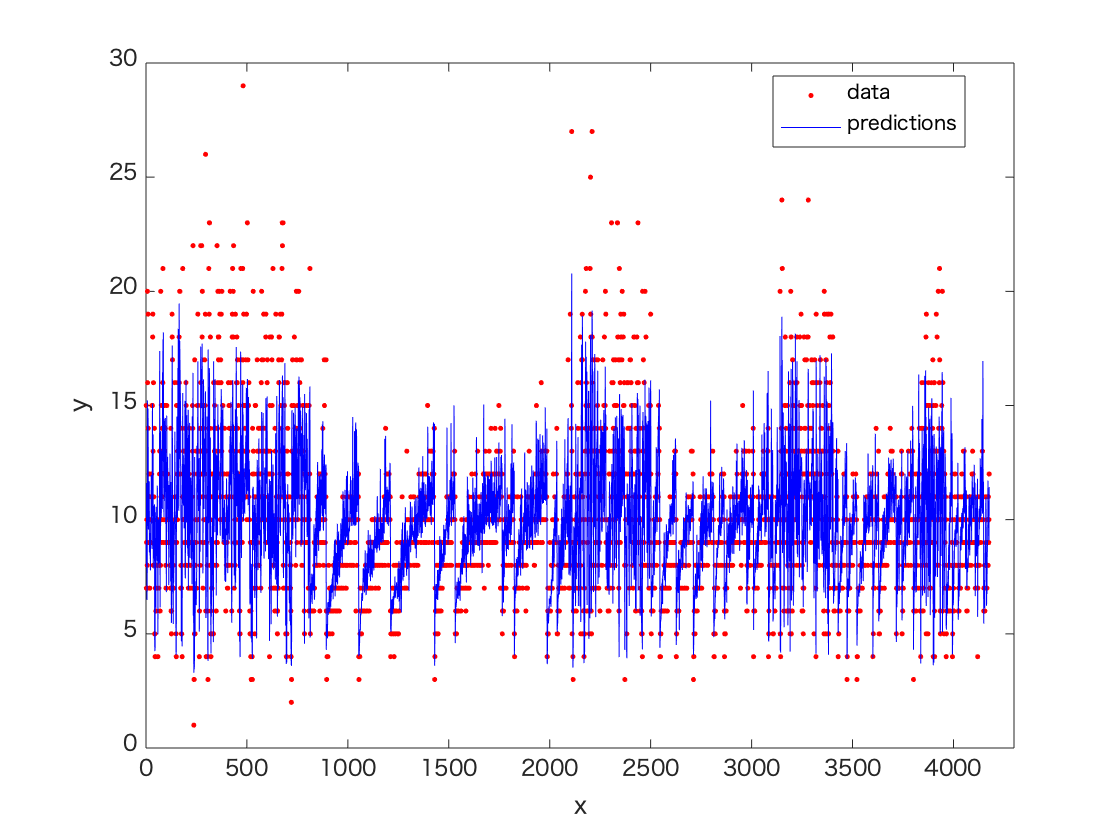

ypred = resubPredict(gprMdl);
figure();
plot(tbl.NoShellRings,'r.');
hold on
plot(ypred,'b');
xlabel('x');
ylabel('y');
legend({'data','predictions'},'Location','Best');
axis([0 4300 0 30]);
hold off;

openExample('stats/TrainGPRModelandPlotPredictionsExample')